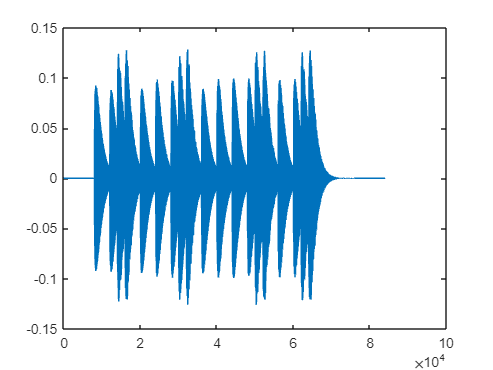

clear
clc

freq = [174.61 184.99 196 207.65 220 233.08 246.94 261.63 277.18 293.66 311.13 329.63 349.23 369.99 392 415.30 440 466.16 493.88 523.25 554.36 587.33 622.25 659.25 698.45]; %各个音符的频率，防止误差累积，不用数值计算方法
srate = 8000; %采样率
xfadet = 0.120; %渐变用时
harmon = [1 0.2 0.3 0.1 0 0 0]; %谐波分量幅度(1x 2x 3x 4x......7x)，不需要的补0占位

%music
musicdat = [0.5 0.25 0.25 0.5 0.5 0.5 0.25 0.25 0.5 0.5 0.5 0.5 0.25 0.25 0.5 0.5 0.25 0.25 0.5; 13 13 17 20 20 22 25 22 20 20 17 17 20 17 13 10 13 17 20; 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]';%音乐数据矩阵[持续时间,音符,幅度]
harmonrepeat = repmat(harmon,length(musicdat(:,1)),1);
musicdat = [musicdat,harmonrepeat];
music = musicgen(freq,musicdat,srate,xfadet,1.5); %生成音乐

%sound
sound(music,8000);
plot(music);